%% Task 5 - Custom spatial dataset and simple town-planning model
clear; clc; close all;

%% Original assignment data
% Columns: Distance from CBD (km), Median house price ($)
% These are median house prices, not official land values.
data = [
    0.5 480000; 2.0 1850000; 3.0 2100000;
    4.0 1900000; 4.5 3200000; 6.0 1750000;
    7.0 1850000; 9.0 1300000; 10.0 1450000;
    11.0 1400000; 12.0 1150000; 13.0 1100000;
    18.0 1200000; 17.0 1150000; 18.0 950000;
    16.0 1050000; 22.0 900000; 20.0 1200000;
    19.0 1300000; 9.0 1250000; 20.0 1000000;
    22.0 880000; 32.0 820000; 30.0 870000;
    50.0 780000; 35.0 1200000; 40.0 1250000;
    65.0 850000; 10.0 1900000; 8.0 1800000
];

suburbs = [
    "Auckland Central"; "Parnell"; "Ponsonby"; "Grey Lynn"; "Herne Bay";
    "Mount Eden"; "Epsom"; "Onehunga"; "Ellerslie"; "Royal Oak";
    "Glen Innes"; "Mount Wellington"; "Howick"; "Pakuranga";
    "Henderson"; "Te Atatu South"; "Massey"; "Albany"; "Browns Bay";
    "Northcote"; "Papatoetoe"; "Manukau"; "Papakura"; "Takanini";
    "Pukekohe"; "Beachlands"; "Orewa"; "Warkworth"; "Devonport"; "Takapuna"
];

distanceCBD = data(:,1);
medianPrice = data(:,2);

%% Approximate suburb-centre latitude and longitude
% These coordinates are used for prototype modelling only.
% They are not official land parcel coordinates.
latitude = [
    -36.8485;  % Auckland Central
    -36.8569;  % Parnell
    -36.8477;  % Ponsonby
    -36.8587;  % Grey Lynn
    -36.8442;  % Herne Bay
    -36.8771;  % Mount Eden
    -36.8910;  % Epsom
    -36.9220;  % Onehunga
    -36.8995;  % Ellerslie
    -36.9120;  % Royal Oak
    -36.8782;  % Glen Innes
    -36.9029;  % Mount Wellington
    -36.8959;  % Howick
    -36.9106;  % Pakuranga
    -36.8815;  % Henderson
    -36.8561;  % Te Atatu South
    -36.8248;  % Massey
    -36.7285;  % Albany
    -36.7141;  % Browns Bay
    -36.8018;  % Northcote
    -36.9783;  % Papatoetoe
    -36.9928;  % Manukau
    -37.0657;  % Papakura
    -37.0474;  % Takanini
    -37.2004;  % Pukekohe
    -36.8844;  % Beachlands
    -36.5885;  % Orewa
    -36.4000;  % Warkworth
    -36.8280;  % Devonport
    -36.7878   % Takapuna
];

longitude = [
    174.7633;  % Auckland Central
    174.7812;  % Parnell
    174.7432;  % Ponsonby
    174.7337;  % Grey Lynn
    174.7307;  % Herne Bay
    174.7641;  % Mount Eden
    174.7740;  % Epsom
    174.7831;  % Onehunga
    174.8072;  % Ellerslie
    174.7750;  % Royal Oak
    174.8560;  % Glen Innes
    174.8374;  % Mount Wellington
    174.9333;  % Howick
    174.8708;  % Pakuranga
    174.6310;  % Henderson
    174.6516;  % Te Atatu South
    174.6078;  % Massey
    174.7010;  % Albany
    174.7470;  % Browns Bay
    174.7492;  % Northcote
    174.8498;  % Papatoetoe
    174.8790;  % Manukau
    174.9439;  % Papakura
    174.9250;  % Takanini
    174.9010;  % Pukekohe
    175.0005;  % Beachlands
    174.6962;  % Orewa
    174.6670;  % Warkworth
    174.7960;  % Devonport
    174.7745   % Takapuna
];

%% Custom features for the town-planning prototype model

n = length(suburbs);

% Higher score means closer to the CBD.
cbdProximityScore = 1 - (distanceCBD ./ max(distanceCBD));

% Group suburbs by distance from the CBD.
distanceBand = strings(n,1);

for i = 1:n
    if distanceCBD(i) <= 5
        distanceBand(i) = "Central / Inner";
    elseif distanceCBD(i) <= 12
        distanceBand(i) = "Inner suburban";
    elseif distanceCBD(i) <= 25
        distanceBand(i) = "Middle suburban";
    else
        distanceBand(i) = "Outer suburban";
    end
end

% Group suburbs into simple value bands based on median house price.
valueBand = strings(n,1);

for i = 1:n
    if medianPrice(i) >= 1700000
        valueBand(i) = "High";
    elseif medianPrice(i) >= 1000000
        valueBand(i) = "Medium";
    else
        valueBand(i) = "Low";
    end
end

% Prototype coastal / harbour-side feature.
coastalSuburbs = [
    "Herne Bay"; "Devonport"; "Takapuna"; "Browns Bay";
    "Beachlands"; "Orewa"; "Warkworth"; "Parnell"; "Auckland Central"
];

coastalAmenityFlag = ismember(suburbs, coastalSuburbs);

% Simple planning-style land type categories.
prototypeLandType = strings(n,1);

for i = 1:n
    if coastalAmenityFlag(i)
        prototypeLandType(i) = "Coastal / harbour urban land";
    elseif distanceCBD(i) <= 5
        prototypeLandType(i) = "Central urban land";
    elseif distanceCBD(i) <= 25
        prototypeLandType(i) = "Suburban residential land";
    else
        prototypeLandType(i) = "Outer urban / satellite town land";
    end
end

% The target is a proxy because the original data gives median house prices, not official land value.
targetType = repmat("Median house price proxy", n, 1);

%% Build and save the custom spatial dataset

Task5Dataset = table( ...
    suburbs, ...
    latitude, ...
    longitude, ...
    distanceCBD, ...
    medianPrice, ...
    cbdProximityScore, ...
    distanceBand, ...
    coastalAmenityFlag, ...
    prototypeLandType, ...
    valueBand, ...
    targetType);

disp(Task5Dataset);

         suburbs          latitude    longitude    distanceCBD    medianPrice    cbdProximityScore      distanceBand       coastalAmenityFlag             prototypeLandType             valueBand            targetType        
    __________________    ________    _________    ___________    ___________    _________________    _________________    __________________    ___________________________________    _________    __________________________

    "Auckland Central"    -36.849      174.76          0.5          4.8e+05           0.99231         "Central / Inner"          true            "Coastal / harbour urban land"  

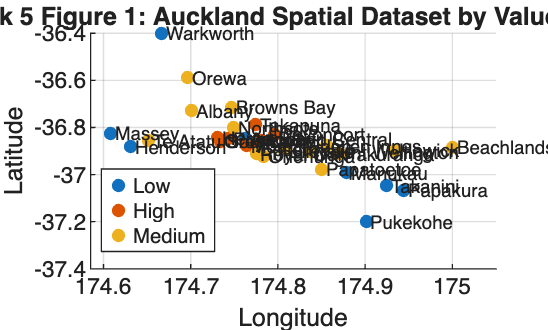


writetable(Task5Dataset, 'Task5_Auckland_CustomSpatialDataset.csv');

%% Figure 1: spatial suburb locations by value band

figure;
gscatter(longitude, latitude, valueBand);
xlabel('Longitude');
ylabel('Latitude');
title('Task 5 Figure 1: Auckland Spatial Dataset by Value Band');
grid on;

for i = 1:n
    text(longitude(i)+0.005, latitude(i), suburbs(i), 'FontSize', 7);
end

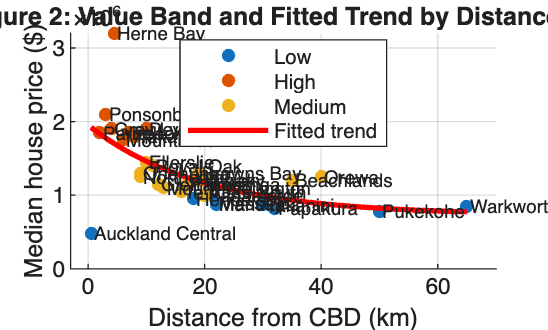


%% Figure 2: Distance from CBD vs price by value band with fitted curve
% This figure shows the relationship between distance from the CBD and median price.
% Colours show value bands, and the red curve shows the general fitted trend.

figure;
gscatter(distanceCBD, medianPrice, valueBand);
hold on;

% Fit an exponential decay model:
% Price = theta1 * exp(theta2 * distanceCBD) + theta3
modelFun = @(theta, d) theta(1) * exp(theta(2) * d) + theta(3);

% Error function for fitting
errorFun = @(theta) sum((medianPrice - modelFun(theta, distanceCBD)).^2);

% Initial parameter guess
theta0 = [2000000, -0.08, 800000];

% Fit the model
thetaFit = fminsearch(errorFun, theta0);

% Create smooth curve values
dSmooth = linspace(min(distanceCBD), max(distanceCBD), 300);
priceFit = modelFun(thetaFit, dSmooth);

% Plot fitted red curve
plot(dSmooth, priceFit, 'r-', 'LineWidth', 2);

xlabel('Distance from CBD (km)');
ylabel('Median house price ($)');
title('Task 5 Figure 2: Value Band and Fitted Trend by Distance from CBD');
grid on;

% Add suburb labels
for i = 1:n
    text(distanceCBD(i)+0.5, medianPrice(i), suburbs(i), 'FontSize', 7);
end

legend('Low', 'High', 'Medium', 'Fitted trend', 'Location', 'best');
hold off;

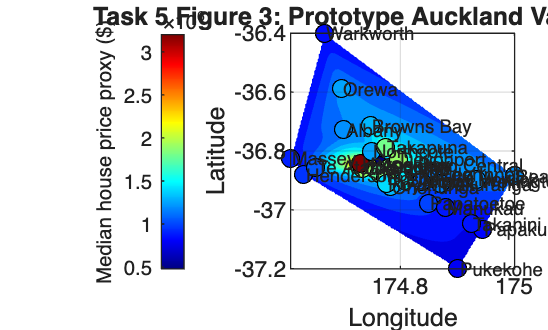


%% Figure 3: prototype Auckland value heat map
% This heat map uses median house price as a proxy for value.
% Blue areas are lower-value proxy areas; red areas are higher-value proxy areas.

x = longitude;
ycoord = latitude;
z = medianPrice;

xGrid = linspace(min(x), max(x), 200);
yGrid = linspace(min(ycoord), max(ycoord), 200);
[Xq, Yq] = meshgrid(xGrid, yGrid);

Zq = griddata(x, ycoord, z, Xq, Yq, 'natural');

figure;
contourf(Xq, Yq, Zq, 20, 'LineColor', 'none');
hold on;

scatter(x, ycoord, 45, z, 'filled', ...
    'MarkerEdgeColor', 'k');

for i = 1:n
    text(x(i)+0.003, ycoord(i), suburbs(i), ...
        'FontSize', 7);
end

colormap(jet);

cb = colorbar('westoutside');
cb.Label.String = 'Median house price proxy ($)';

xlabel('Longitude');
ylabel('Latitude');
title('Task 5 Figure 3: Prototype Auckland Value Heat Map');

grid on;
axis tight;

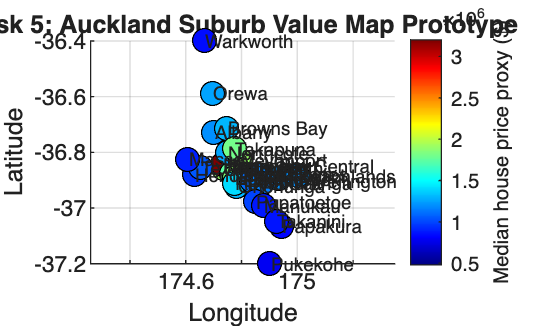


%% Task 5 Figure: Geographic-style suburb value plot
% This plots each suburb using longitude and latitude.
% Colour represents median house price proxy.

figure;

scatter(longitude, latitude, 80, medianPrice, 'filled', ...
    'MarkerEdgeColor', 'k');

colormap(jet);
cb = colorbar;
cb.Label.String = 'Median house price proxy ($)';

xlabel('Longitude');
ylabel('Latitude');
title('Task 5: Auckland Suburb Value Map Prototype');

grid on;
axis equal;

% Add suburb labels
for i = 1:n
    text(longitude(i)+0.003, latitude(i), suburbs(i), 'FontSize', 7);
end



%% Interactive planner input model
% A planner manually enters latitude and longitude.
% The model checks if the point is valid urban land, reserve/parkland, or possible sea/harbour.
% If the point is valid, the model returns the nearest suburb and estimated value.

% disp(" ");
% disp("Task 5 Planner Input Model");
% disp("-----------------------------------------");
% disp("Enter a latitude and longitude for an Auckland location.");
% disp("Example near Mount Eden: latitude = -36.8770, longitude = 174.7640");
% disp("-----------------------------------------");
% 
% plannerLat = input("Enter latitude: ");
% plannerLon = input("Enter longitude: ");
% 
% useCustomPrice = input("Do you want to enter your own estimated house/land price? Type yes or no: ", "s");
% 
% if strcmpi(useCustomPrice, "yes")
%     customPrice = input("Enter custom estimated price in dollars: ");
% else
%     customPrice = NaN;
% end
% 
% %% Prototype land-status check
% % A real town-planning model would use official GIS polygon layers.
% % These simple approximate coordinate rules show the idea only.
% 
% landStatus = "Valid urban land";
% 
% % Cornwall Park / One Tree Hill approximate area.
% if plannerLat < -36.905 && plannerLat > -36.925 && ...
%    plannerLon > 174.775 && plannerLon < 174.795
%     landStatus = "Reserve / parkland";
% end
% 
% % Waitakere Ranges approximate area.
% if plannerLat < -36.80 && plannerLat > -37.05 && ...
%    plannerLon > 174.45 && plannerLon < 174.62
%     landStatus = "Parkland / regional reserve";
% end
% 
% % Simple sea / harbour prototype area.
% if plannerLon > 174.82 && plannerLat > -36.86 && plannerLat < -36.78
%     landStatus = "Possible sea / harbour area";
% end
% 
% disp("-----------------------------------------");
% disp("Planner input result:");
% disp("Input latitude: " + string(plannerLat));
% disp("Input longitude: " + string(plannerLon));
% disp("Land status: " + landStatus);
% 
% if landStatus ~= "Valid urban land"
% 
%     disp("No normal land value estimate should be returned for this location.");
% 
% else
% 
%     % Find the nearest known suburb point using latitude/longitude distance.
%     locationDistance = sqrt((latitude - plannerLat).^2 + ...
%                             (longitude - plannerLon).^2);
% 
%     [~, nearestIdx] = min(locationDistance);
% 
%     estimatedSuburb = suburbs(nearestIdx);
%     estimatedValueBand = valueBand(nearestIdx);
%     estimatedLandType = prototypeLandType(nearestIdx);
%     estimatedMedianPrice = medianPrice(nearestIdx);
% 
%     disp("Nearest suburb: " + estimatedSuburb);
%     disp("Estimated value band: " + estimatedValueBand);
%     disp("Estimated prototype land type: " + estimatedLandType);
%     disp("Estimated median house price proxy: $" + string(estimatedMedianPrice));
% 
%     if ~isnan(customPrice)
% 
%         if customPrice >= 1700000
%             customValueBand = "High";
%         elseif customPrice >= 1000000
%             customValueBand = "Medium";
%         else
%             customValueBand = "Low";
%         end
% 
%         disp("User-entered custom price: $" + string(customPrice));
%         disp("Custom price value band: " + customValueBand);
%     end
% end